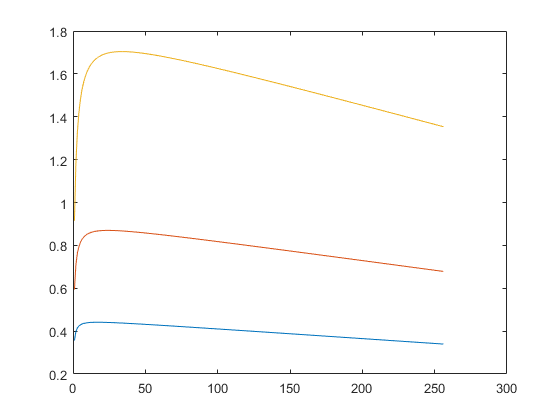

close all;
clear;
clc;

M = [64 128 256];
K = 256;
L = 1:K;

rho_db = -20;
rho    = 10^(rho_db/10);

tau_c = 1000;
tau_p = L;
ratio_dl_ul = 0.5;

se_iid_rayleigh = @(tau_p,tau_c,L,M,rho) ratio_dl_ul*(1 - tau_p/tau_c).*L.*log2(1 + rho*M./(L + rho*(L-1)));

plot(L,se_iid_rayleigh(tau_p,tau_c,L,M(1),rho));
hold on;
plot(L,se_iid_rayleigh(tau_p,tau_c,L,M(2),rho));
plot(L,se_iid_rayleigh(tau_p,tau_c,L,M(3),rho));